% Опис передатних функцій для каналів керування та збурення

% Передатна функція каналу керування: Gг(p) → T3м(p)
Wc = tf([10115 7590 42], [198062 159339 31709 344 0.96]);

% Передатна функція каналу збурення: T1м(p) → T3м(p)
Wd = tf([-198062 -157139 -29952 -2.7 0.89], [198062 159339 31709 344 0.96]);

% Побудова перехідної характеристики
figure;
step(Wc, Wd);

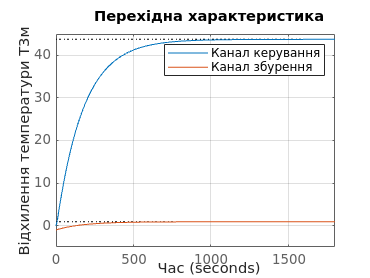

title('Перехідна характеристика');
legend('Канал керування', 'Канал збурення');
xlabel('Час');
ylabel('Відхилення температури T3м');
grid on;

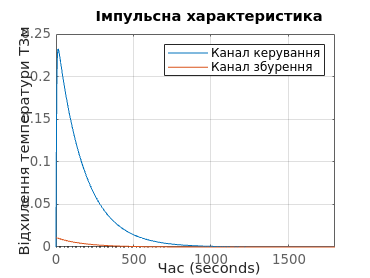


% Побудова імпульсної характеристики
figure;
impulse(Wc, Wd);
title('Імпульсна характеристика');
legend('Канал керування', 'Канал збурення');
xlabel('Час');
ylabel('Відхилення температури T3м');
grid on;